## Read Data from Data Files

Intan can save data in chunks of 60 secs into a data folder. You can specify the maximum number of files that you want to plot in order to avoid long load, plot, and processing times.

max_files = 5;

MATLAB will open a dialog box and ask you to select a file. Open the folder with the Intan data files that you want to load. Select one of the files and click "OK."

[file, path] = uigetfile('*.rhd');
fnames = dir(fullfile(path,'*.rhd'));
disp([newline 'Processing ' num2str(length(fnames)) ' files:']);


Processing 30 files:


for i=1:min(max_files,length(fnames))
    disp(fnames(i).name);
end

20210721_20210726_210726_141503.rhd
20210721_20210726_210726_141603.rhd
20210721_20210726_210726_141703.rhd
20210721_20210726_210726_141803.rhd
20210721_20210726_210726_141903.rhd


s = input([newline 'Do you want to analyze these files? [y]/n'], 's');

% Quit if user does not want to continue
if ~(strcmp(s,'y') | strcmp(s,'Y') | strcmp(s,'')); return; end

Iterate through each data file in the specified folder, or up to the maximum number of files to analyze, and load the data.

% Instantiate data object
dat = {};
dat.t_amplifier = [];
dat.amplifier_data = [];
dat.board_dig_in_data = [];

% Load data files and store data in data object
for i=1:min(max_files,length(fnames))
    disp([newline 'Loading: ' fnames(i).name]);
    
    % Use modified version of downloaded Intan script to pull variables
    % into namespace.
    [t_amplifier, amplifier_data, board_dig_in_data, frequency_parameters] = read_Intan_RHD2000_file_nongui(fnames(i).name, path);
    
    % Append time data
    dat.t_amplifier(end+1:end+length(t_amplifier)) = t_amplifier;
    
    % Append amplifier data
    if length(dat.amplifier_data) == 0
        dat.amplifier_data = amplifier_data;
    else
        dat.amplifier_data(:,end+1:end+length(t_amplifier)) = amplifier_data;
    end
    
    % You can also pull board_dig_data, board_adc_data, and other Intan
    % data variables into namespace.
end


Loading: 20210721_20210726_210726_141503.rhd


Reading Intan Technologies RHD2000 Data File, Version 3.0

Found 32 amplifier channels.
Found 3 auxiliary input channels.
Found 0 supply voltage channels.
Found 0 board ADC channels.
Found 0 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 60.000 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Done!  Elapsed time: 1.3 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.




Loading: 20210721_20210726_210726_141603.rhd


Reading Intan Technologies RHD2000 Data File, Version 3.0

Found 32 amplifier channels.
Found 3 auxiliary input channels.
Found 0 supply voltage channels.
Found 0 board ADC channels.
Found 2 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 60.000 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Done!  Elapsed time: 1.5 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.




Loading: 20210721_20210726_210726_141703.rhd


Reading Intan Technologies RHD2000 Data File, Version 3.0

Found 32 amplifier channels.
Found 3 auxiliary input channels.
Found 0 supply voltage channels.
Found 0 board ADC channels.
Found 2 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 60.000 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Done!  Elapsed time: 1.5 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.




Loading: 20210721_20210726_210726_141803.rhd


Reading Intan Technologies RHD2000 Data File, Version 3.0

Found 32 amplifier channels.
Found 3 auxiliary input channels.
Found 0 supply voltage channels.
Found 0 board ADC channels.
Found 2 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 60.000 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Done!  Elapsed time: 1.5 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.




Loading: 20210721_20210726_210726_141903.rhd


Reading Intan Technologies RHD2000 Data File, Version 3.0

Found 32 amplifier channels.
Found 3 auxiliary input channels.
Found 0 supply voltage channels.
Found 0 board ADC channels.
Found 2 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 60.000 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Done!  Elapsed time: 1.4 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.




disp([newline 'Data successfully loaded!!']);


Data successfully loaded!!


## Filter and Plot Data

How many channels do you want plotted in each figure? Recommended number is 8 as this matches the number of contacts on each thread and it helps to group channels into manageable axes.

n_chan_per_plot = 8;

You can plot data using a few tricks to help filter out unwanted common mode noise. In order to plot data as it is recorded by the amplifier, set this value to 0. If you want to subtract one channel from ALL OTHER channels, set this variable to a single number corresponding to the channel to subtract from the others. This will treat the specified channel as a "reference." You can also subtract a channel from each of the channels that are plotted within a figure. For example, if you have 32 channels and n_chan_per_plot is set to 8, there will be 4 figures. You can then specify an array with 4 elements such that the first element of the array will be the channel subtracted from the axes in the first figure, the second element in the array will be the channel subtracted from the axes in the second figure, etc.

% chan_subtract = 0;
% chan_subtract = 7;
chan_subtract = [7 15 20 26];

Specify the low cutoff and high cutoff for the bandpass filter.

filt_lo = 350;
filt_hi = 7500;

Instantiate the figure(s) with specified number of axes, filter data, and plot data on axes.


Processing CH1



Processing CH2



Processing CH3



Processing CH4



Processing CH5



Processing CH6



Processing CH7



Processing CH8



Processing CH9



Processing CH10



Processing CH11



Processing CH12



Processing CH13



Processing CH14



Processing CH15



Processing CH16


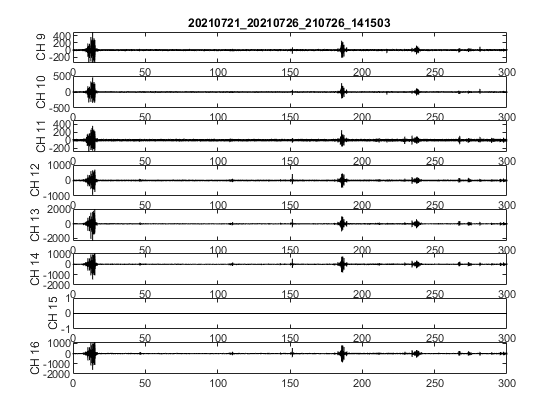


Processing CH17



Processing CH18



Processing CH19



Processing CH20


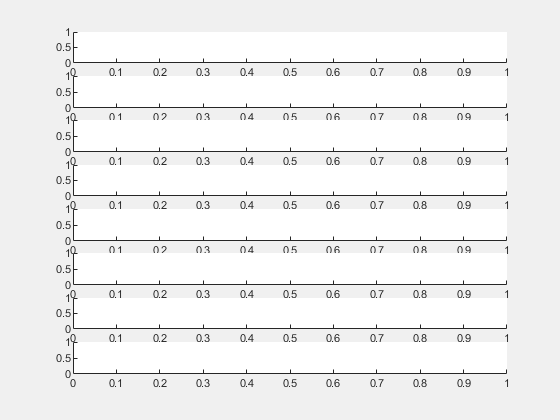


Processing CH21


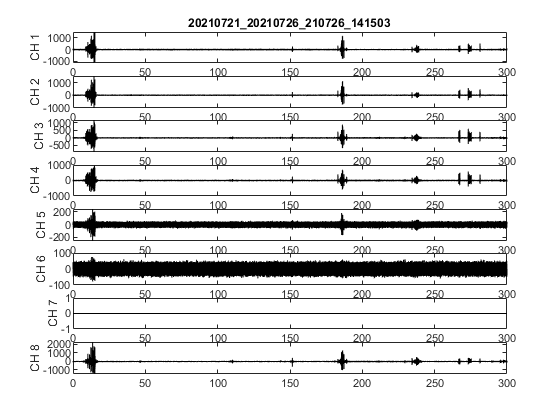


Processing CH22



Processing CH23



Processing CH24


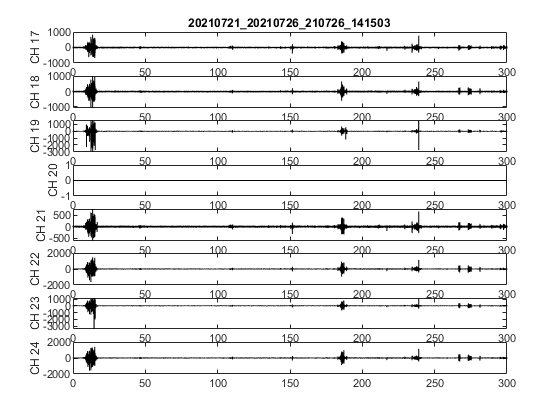


Processing CH25



Processing CH26



Processing CH27



Processing CH28



Processing CH29



Processing CH30



Processing CH31



Processing CH32


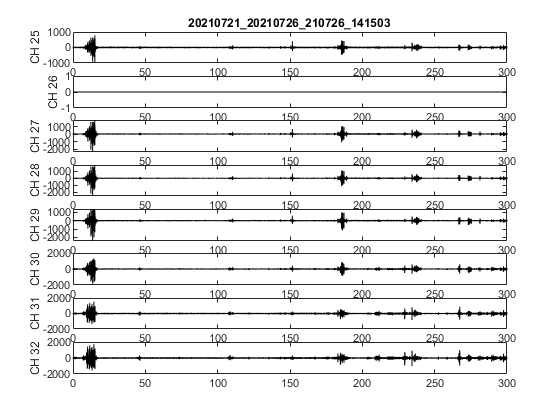

% Determine figure title
fig_title = split(path,'\');
fig_title = strrep(fig_title{end-1},'_','\_');

% Instantiate variable to store filtered data information for later
% analysis
dat.filtered_data = zeros(size(dat.amplifier_data));

% Plot data with n_chan_per_plot in each figure
for k=1:ceil(size(dat.amplifier_data,1)/n_chan_per_plot)
    figure();
    axs = {};
    for i=1:n_chan_per_plot
        axs{end+1} = subplot(n_chan_per_plot,1,i);
    end
    
    % This line generates separate figure windows in addition to the
    % embedded figures.
    set(gcf, 'Visible', 'on');
    drawnow();

    % Plot data one channel at a time
    for i=1:n_chan_per_plot
        ch_num = i+(k-1)*n_chan_per_plot;
        disp([newline 'Processing CH' num2str(ch_num)]);
        
        if all(chan_subtract == 0)
            % If chan_subtract == 0 --> plot each channel without subtraction
            % (unipolar with RHD2132 or bipolar with RHD2216)
            wav = bandpass_filtfilt(dat.amplifier_data(ch_num,:),frequency_parameters.amplifier_sample_rate,filt_lo,filt_hi,'hanningfir');
        else
            % If chan_subtract > 0 --> plot each channel in this figure
            % as a subtraction between two unfiltered channels, then filter
            % before plotting.
            if length(chan_subtract) == 1
                wav = bandpass_filtfilt(dat.amplifier_data(ch_num,:)-dat.amplifier_data(chan_subtract,:),frequency_parameters.amplifier_sample_rate,filt_lo,filt_hi,'hanningfir');
            else
                assert(length(chan_subtract)==ceil(size(dat.amplifier_data,1)/n_chan_per_plot),['Invalid format: chan_subract. If multiple channels specified, must be ' num2str(ceil(size(dat.amplifier_data,1)/n_chan_per_plot)) ' elements.']);
                wav = bandpass_filtfilt(dat.amplifier_data(ch_num,:)-dat.amplifier_data(chan_subtract(k),:),frequency_parameters.amplifier_sample_rate,filt_lo,filt_hi,'hanningfir');
            end                
        end

        % Add filtered data to storage object
        dat.filtered_data(ch_num,:) = wav;
        plot(axs{i}, dat.t_amplifier, wav, 'k-');
        ylabel(axs{i}, ['CH ' num2str(ch_num)]);
        drawnow();
    end

    title(axs{1}, fig_title);
    linkaxes([axs{:}], 'x');
end

## Detect Spikes and Cluster Waveforms

Specify which channel of filtered data to analyze.

chan_clust = 1;

wav = dat.filtered_data(chan_clust,:);
figure();
plot(dat.t_amplifier, wav, 'k-');
drawnow();
hold on;

Specify the level of sensitivity for spike detection. The threshold is set using a robust estimator derived for neural activity.

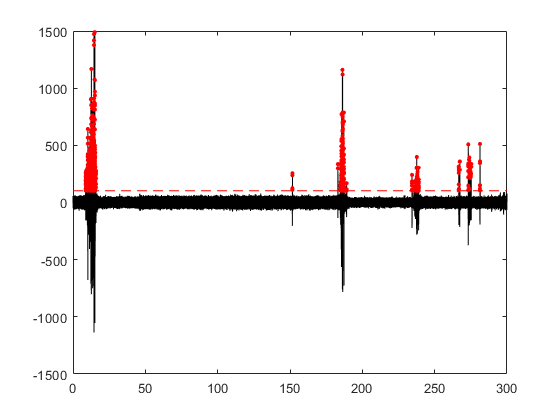

std_th_val = 7;

std_th = std_th_val*(median(abs(wav))/0.6745);
plot(dat.t_amplifier([1 end]), [std_th std_th], 'r--');
% Generate separate figure window;
set(gcf, 'Visible', 'on');
drawnow();

down_ix = find(diff(sign(wav-std_th)) == -2);
up_ix = find(diff(sign(wav-std_th)) == 2);

if length(up_ix) > 0 & length(down_ix) > 0
    if up_ix(1) > down_ix(1); down_ix(1) = []; end
    if up_ix(end) > down_ix(end); up_ix(end) = []; end

    [m,ix] = max(wav(up_ix(1):down_ix(1)));
    pks = [m,ix];

    for i=2:length(up_ix)
        [m,ix] = max(wav(up_ix(i):down_ix(i)));
        pks(end+1,:) = [m,ix];
    end

    pk_ixs = plus(pks(:,2),up_ix')-1;
    scatter(dat.t_amplifier(pk_ixs), wav(pk_ixs), 10, 'filled', 'r');
    drawnow();
else
    disp('No spikes detect.');
end

Specify the window duration with which to perform PCA and clustering. Plot sample of waveforms.

spk_win = 5; % ms
wavs_to_plot = 250; % specify number of waveforms to plot for preview

win_ixs = spk_win/1000.*frequency_parameters.amplifier_sample_rate;

% Dropping peaks that are too close to the beginning or end of the file
pks = pk_ixs;
drop_ixs = find(pks < (floor(win_ixs/2)+1));
if length(drop_ixs) > 0; pks(drop_ixs) = []; end
drop_ixs = find(pks > length(wav) - (floor(win_ixs/2)+1));
if length(drop_ixs) > 0; pks(drop_ixs) = []; end


wav_clips = arrayfun(@(x) wav((pks(x)-floor(win_ixs/2)):(pks(x)+floor(win_ixs/2))), [1:length(pks)], 'UniformOutput', false);
wav_mat = zeros(length(wav_clips),length(wav_clips{1}));
for i=1:length(wav_clips)
    wav_mat(i,:) = wav_clips{i};
end
disp(['Plotting ' num2str(wavs_to_plot) ' waveforms']);

Plotting 250 waveforms


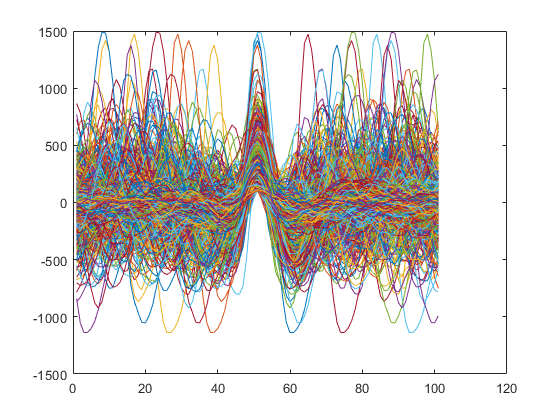

figure();
plot(wav_mat');

Specify the number of clusters you'd like to have in the end. Perform PCA decomposition and then cluster using k-means.

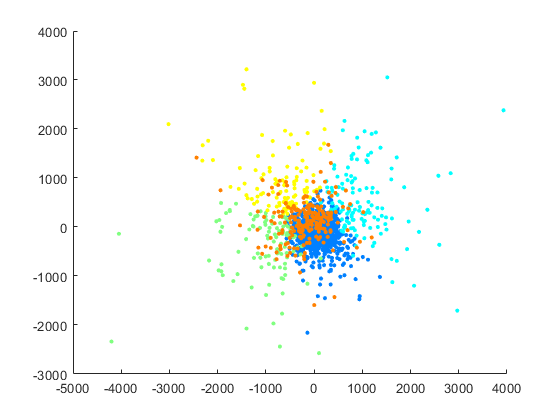

n_clust = 5;

cs = jet(n_clust);

[~,scores,~] = pca(wav_mat);
[idx,C] = kmeans(scores(:,1:3),n_clust);

figure();
hold on;
for i=1:n_clust
    ixs = find(idx == i);
    scatter(scores(ixs,1), scores(ixs,2),10,cs(i,:),'filled');
end

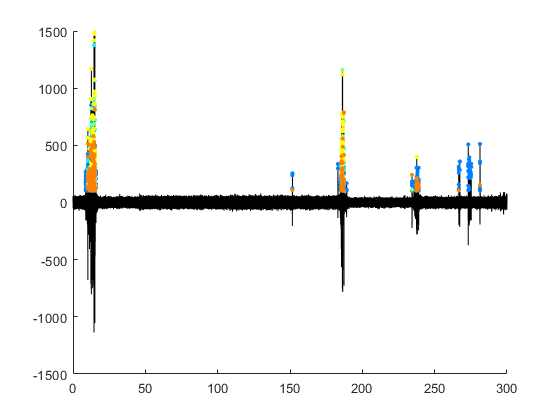


figure();
hold on;
plot(dat.t_amplifier, wav, 'k-');
for i=1:n_clust
    ixs = find(idx == i);
    scatter(dat.t_amplifier(pk_ixs(ixs)), wav(pk_ixs(ixs)), 10,cs(i,:), 'filled');
end